**LEP 5-6 : Robert worries What if..**

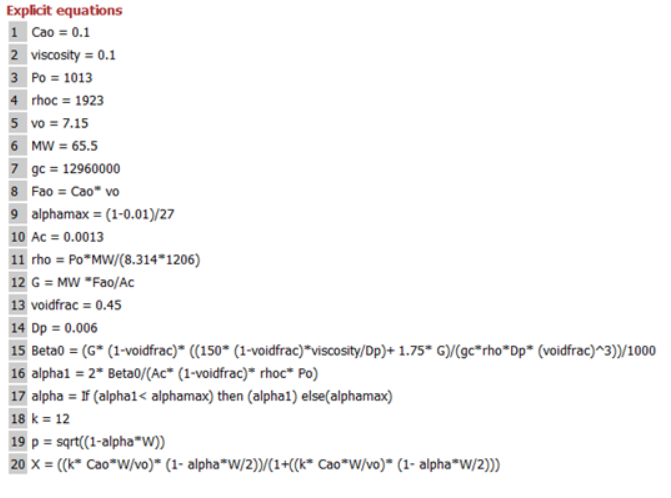

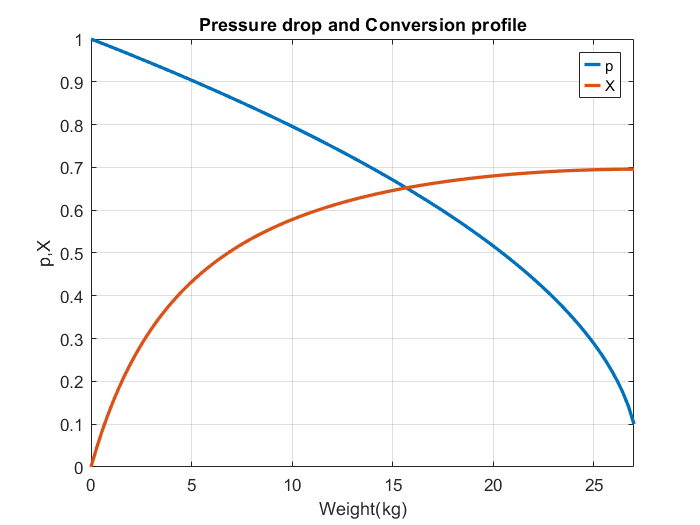


Cao=0.1;
voidfrac=0.45;
Dp=0.006;
Po=1013;
Ac=0.0013;
vo=7.15;
k=12;
MW=65.5;
rho = Po*MW/(8.314*1206);
rhoc = 1923;
viscosity = 0.1;
gc = 12960000;
Fao = Cao* vo;
G = MW* Fao/Ac;
Beta0= (G*(1-voidfrac)*((150*(1 - voidfrac)* viscosity/Dp) + 1.75*G)/(gc*rho*Dp* (voidfrac).^3))/1000;
alpha1 = 2* Beta0/(Ac* (1 - voidfrac) *rhoc* Po);
alphamax = (1 - 0.01)/27;
if alpha1 < alphamax
    alpha = alpha1;
else alpha=alphamax;  
end
W=linspace(0,27,100);
z=size(W);
for i=1:z(1,2)
p(i) = (1 - alpha* W(i)).^0.5;
a(i) = (k* Cao* W(i)/vo)* (1 - alpha* W(i)/2);
X(i) = a(i)/(1 + a(i));
end
plot(W,p,W,X,'LineWidth',2)
xlabel('Weight(kg)')
ylabel('p,X')
leg=legend('p','X');
leg.ItemTokenSize=[10,10];
axis([0 27 0 1])
title('Pressure drop and Conversion profile')
grid on